main_dir = "D:\OneDrive\OneDrive - UW-Madison\Sunduz\processed data\settingSSoS\n100-k2-p_in2btw25-p_out1btw1\";
% main_dir = "C:\OneDrive\OneDrive - UW-Madison\Sunduz\processed data\settingSSoS\n100-k2-p_in2btw25-p_out1btw1\"
data_dir = "r_time0-time_horizon2-r_subject0-num_subjects16\0\";

zS = load(main_dir+data_dir+"z_pred.mat").zS;
G = load(main_dir+data_dir+"G.mat").G;
O = load(main_dir+data_dir+"O.mat").O;
ari = load(main_dir+data_dir+"aris.mat").aris;

max_color_value = size(ari);
max_color_value = max_color_value(3);
cm = colormap(jet(max_color_value));
mm_ari = squeeze(mean(mean(ari)));
% col = ceil(mm_ari*max_color_value);
sz = 50;

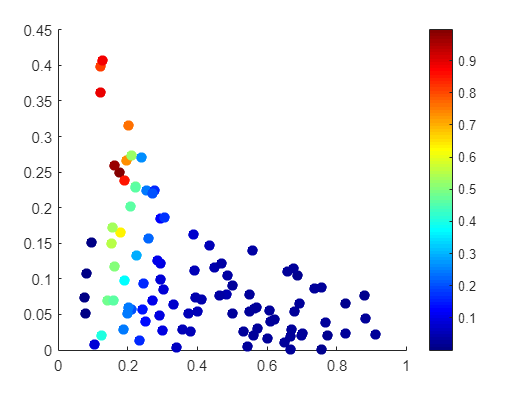

scatter(G,O,sz, mm_ari,"filled");
colorbar;

% for i = 1:1:max_color_value
%     selected_color = cm(col(i),:);
%     plot(G(i),O(i),".","color",selected_color);
%     hold on;
% end